# 解析 .hmod 文件

假设 hank2_ssj.hmod 已经位于工作文件夹之中。在 MATLAB 中调用：

clear_hans
hans hank2_ssj

Parsing...ok!
Compiling dpopt_vfi
Building with 'MinGW64 Compiler (C++)'.
MEX completed successfully.


ans = struct with fields:
               parameters: {'beta'  'sigma'  'varphi'  'nu'  'chi0'  'chi1'  'omega'  'ra'  'r'  'w'  'tau'  'N'}
                var_shock: 'e'
                var_state: {'b'  'a'}
              var_pre_vfi: 'coh'
               var_policy: {'bp'  'ap'  'c'}
                  var_aux: {'chi'  'uce'}
                  var_agg: {'r'  'pii'  'Y'  'K'  'N'  'w'  'p'  'd'  'Bh'}
            var_agg_shock: 'm_shock'
           var_agg_params: {'G'  'Y_star'  'muw'  'kappap'  'kappaw'  'phi_y'  'beta'  'delta'  'omega'  'alpha'  'Bg'  'rstar'  'mup'  'phi'  'varphi'  'nu'  'epsI'  'Z'}
           var_agg_assign: {'ii'  'pshare'  'ra'  'I'  'psip'  'Q'  'tau'}
    var_agg_in_ind_params: {'r'  'N'  'w'  'ra'  'tau'}
            var_ind_in_eq: {'c'  'chi'  'uce'  'ap'  'bp'}


如上所示，HANS 解析了 hmod 文件，编译了 mex 文件，并且返回了一个描述模型的结构体。

第一行中的 clear_hans 清空了之前生成的所有缓存文件。

# 校准与稳态均衡

调用生成的代码 solve_cali 来校准模型参数，使其满足稳态均衡的数据目标。通过构造，校准的结果也返回了校准参数对应的稳态均衡。

tic;
cali_rslt = solve_cali;

Evaluating at var_agg: 0.976, 6.416, 
VFI converged (metric_v) 5.93717e-08, (metric_pol) 0 in 745 iterations
Range of b: 0, 21.3544
Range of a: 0, 76.6147
Equilbirium residual: -2.11182, -0.137683, 

     Iteration    Line Search     Func-count    ||f(x)||^2     fnorm(x)      Norm of Step      Step Size      Algorithm

             0              0              1   4.478758e+00   2.116308e+00
Evaluating at var_agg: 0.9761, 6.416, 
VFI converged (metric_v) 1.76167e-08, (metric_pol) 0 in 566 iterations
Range of b: 0, 21.3544
Range of a: 0, 76.6147
Equilbirium residual: -1.99684, -0.128231, 
Evaluating at var_agg: 0.976, 6.41664, 
VFI converged (metric_v) 2.4074e-08, (metric_pol) 0 in 551 iterations
Range of b: 0, 21.3544
Range of a: 0, 76.6147
Equilbirium residual: -2.11176, -0.137825, 
Evaluating at var_agg: 0.977823, 6.57271, 
VFI converged (metric_v) 5.67098e-08, (metric_pol) 0 in 686 iterations
Range of b: 0, 21.3544
Range of a: 0, 91.6827
Equilbirium residual: 0.352755, 0.0130091, 


fprintf('Time used for Calibration:\n');

Time used for Calibration:


toc;

Elapsed time is 151.809596 seconds.


我们可以查看 cali_rslt 中的数值：

cali_rslt

cali_rslt = struct with fields:
                vfi_rslt: [1×1 struct]
                   stats: [1×1 struct]
                 var_agg: [1×1 struct]
                    dist: [3×50×70 double]
              parameters: [1×1 struct]
          var_agg_params: [1×1 struct]
             shock_trans: [3×3 double]
    shock_invariant_dist: [3×1 double]
                   resid: [2×1 double]
               exit_flag: 1
               rslt_type: 'ss'
           solver_output: [1×1 struct]
           ind_rslt_dict: [1×1 ArrayKeyMap]


在计算出所有的参数及其对应的稳态均衡之后，我们继续进行转移路径的计算。然而，作为一项额外的验证措施，我们可以通过将返回的 cal_rslt 结构传递给 solve_ss 函数来求解稳态均衡：

tic;
ss_rslt = solve_ss(cali_rslt);

Evaluating at var_agg: 0.0125, 1, 
VFI converged (metric_v) 0.00771125, (metric_pol) 0 in 33 iterations
Range of b: 0, 21.3544
Range of a: 0, 83.8117
Equilbirium residual: -7.92235e-06, 1.57066e-10, 

     Iteration    Line Search     Func-count    ||f(x)||^2     fnorm(x)      Norm of Step      Step Size      Algorithm

             0              0              1   6.276356e-11   7.922346e-06
Evaluating at var_agg: 0.0125, 1, 
VFI result reused
Range of b: 0, 21.3544
Range of a: 0, 83.8117
Equilbirium residual: -7.92235e-06, 1.57066e-10, 


fprintf('Time used for solving stationary equilibrium:\n');

Time used for solving stationary equilibrium:


toc;

Elapsed time is 0.435768 seconds.


正如预期的那样，初始条件已经满足了稳态均衡的所有条件。因此，计算在初始迭代之后立即停止。

所有的稳态均衡的信息都在结构 ss_rslt 中返回。

ss_rslt

ss_rslt = struct with fields:
                vfi_rslt: [1×1 struct]
                   stats: [1×1 struct]
                 var_agg: [1×1 struct]
                    dist: [3×50×70 double]
              parameters: [1×1 struct]
          var_agg_params: [1×1 struct]
             shock_trans: [3×3 double]
    shock_invariant_dist: [3×1 double]
                   resid: [2×1 double]
               exit_flag: 1
               rslt_type: 'ss'
           solver_output: [1×1 struct]
           ind_rslt_dict: [1×1 ArrayKeyMap]


我们可以检查均衡变量的值并验证其满足了所有校准目标。

ss_rslt.var_agg

ans = struct with fields:
          r: 0.0125
          Y: 1
    m_shock: 0
         ra: 0.0125
         mc: 0.9850
          K: 10
          N: 1
          w: 0.6600
          d: 0.1400
          p: 11.2000
        tau: 0.3561
      rstar: 0.0125
     Y_star: 1
        pii: 0
         Bh: 1.0400


为了直观展现结果，我们可以将给定的个体冲击下的策略函数绘制在一个三维图形中：

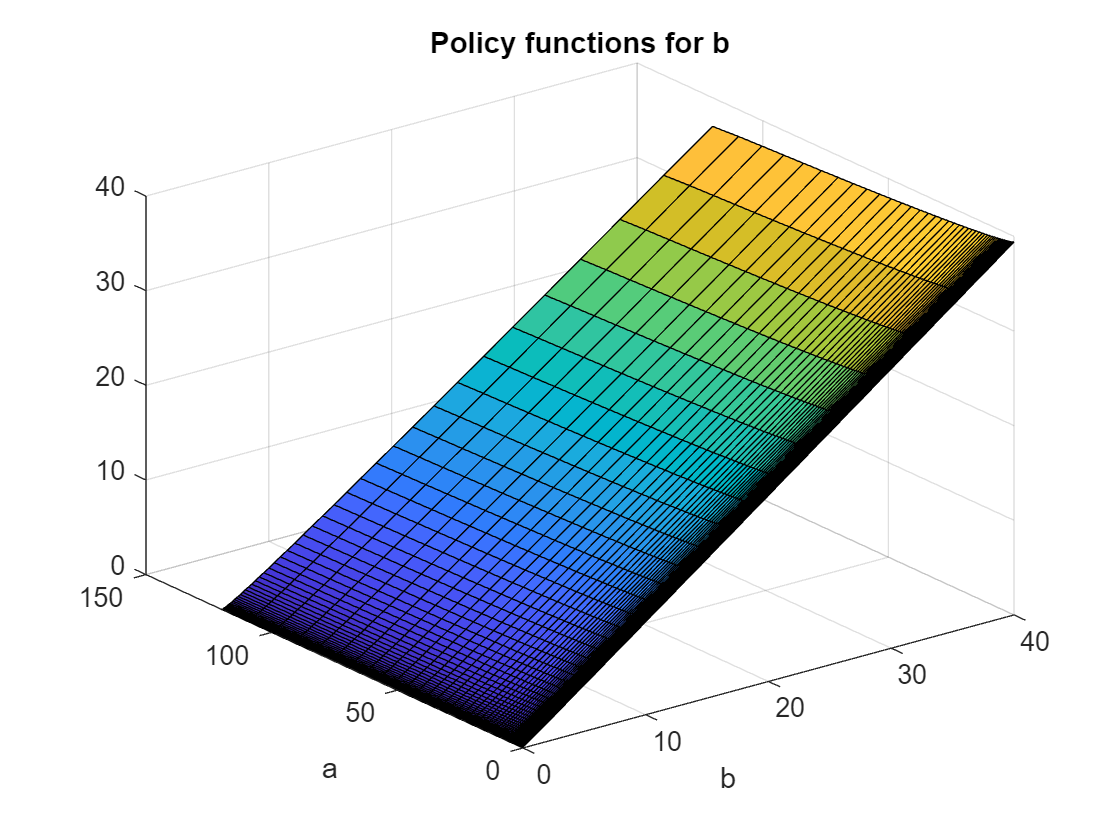

% Pick an idiosyncratic shock and the corresponding (b,a) mesh in 2-D
shock_idx = 2;
b_mesh_2d = squeeze(ss_rslt.vfi_rslt.var_state_mesh.b_mesh(shock_idx,:,:));
a_mesh_2d = squeeze(ss_rslt.vfi_rslt.var_state_mesh.a_mesh(shock_idx,:,:));

% Plot the VFI Policy in 3-D Mesh
surf(b_mesh_2d,a_mesh_2d,squeeze(ss_rslt.vfi_rslt.var_policy.bp(shock_idx,:,:)))
xlabel('b');
ylabel('a');
title('Policy functions for b');

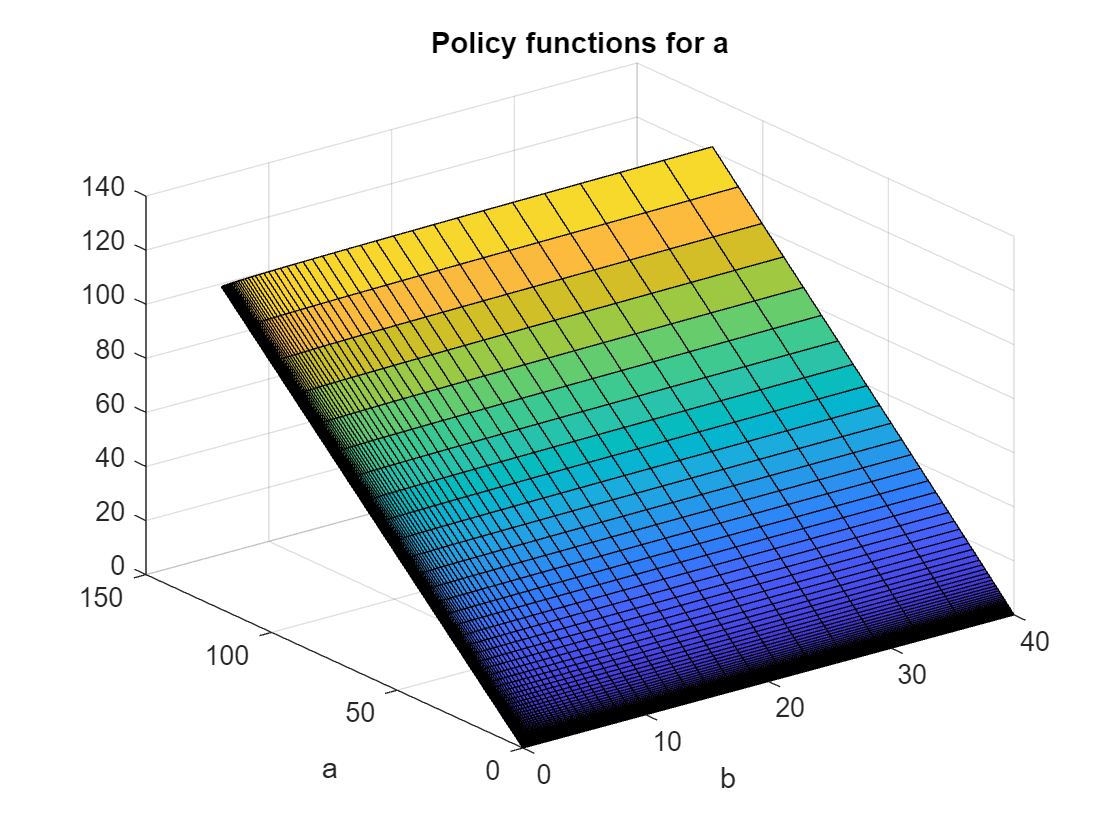


surf(b_mesh_2d,a_mesh_2d,squeeze(ss_rslt.vfi_rslt.var_policy.ap(shock_idx,:,:)))
xlabel('b');
ylabel('a');
title('Policy functions for a');

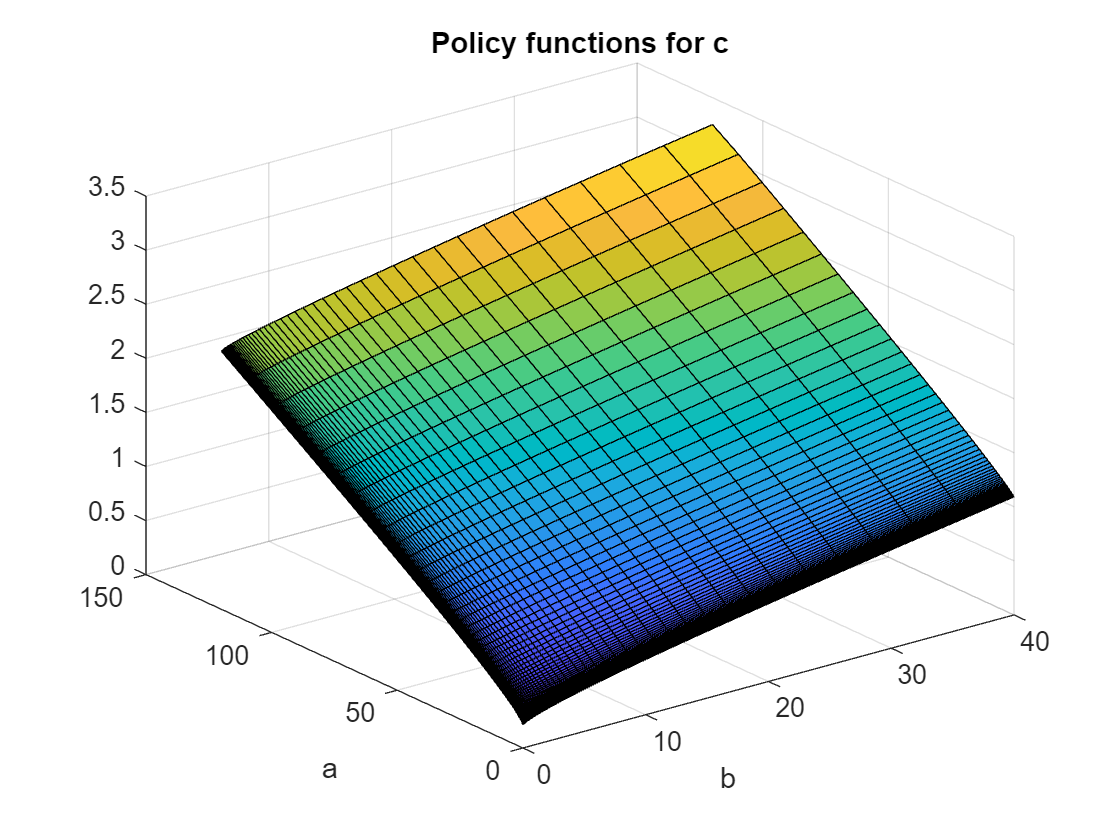


surf(b_mesh_2d,a_mesh_2d,squeeze(ss_rslt.vfi_rslt.var_policy.c(shock_idx,:,:)));
xlabel('b');
ylabel('a');
title('Policy functions for c');

我们还可以绘制（b, a）上的联合稳态分布，以及b或a的边际分布。

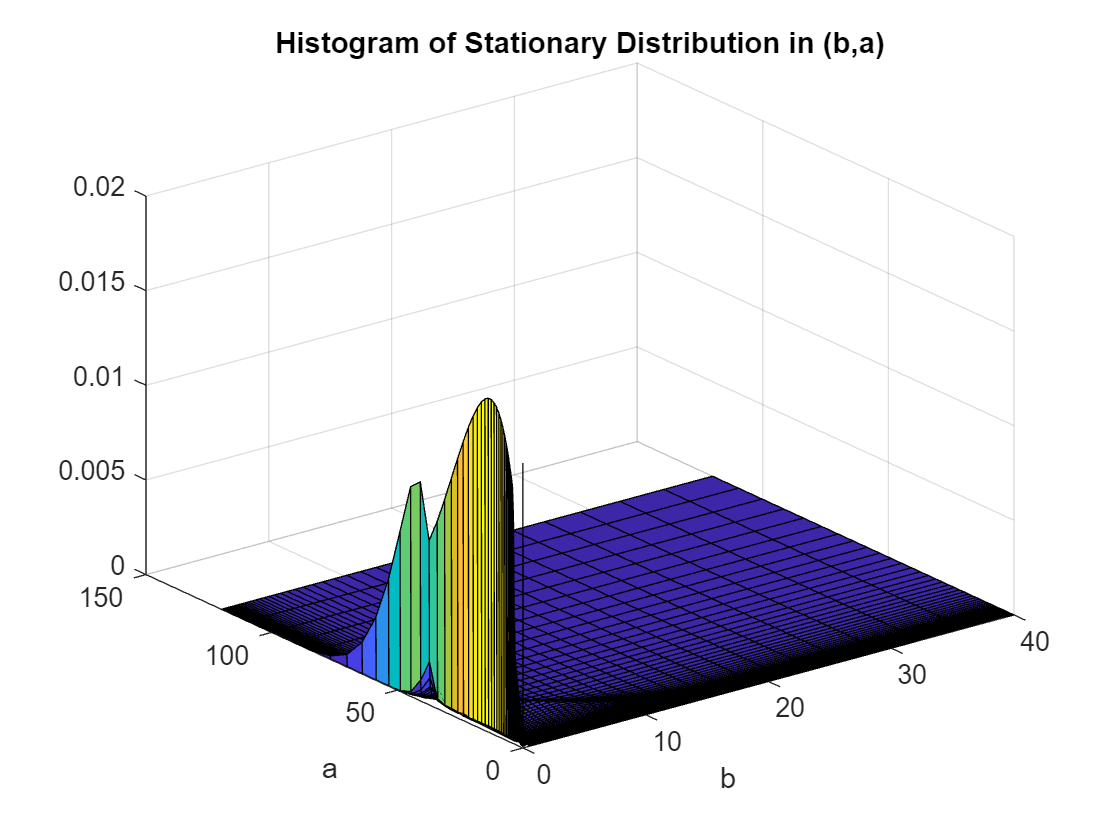

% Extract (b,a) mesh in 2-D
b_mesh_2d = squeeze(ss_rslt.vfi_rslt.var_state_mesh.b_mesh(1,:,:));
a_mesh_2d = squeeze(ss_rslt.vfi_rslt.var_state_mesh.a_mesh(1,:,:));

bgrid = ss_rslt.vfi_rslt.var_state.b(:); % b grid
agrid = ss_rslt.vfi_rslt.var_state.a(:); % a grid

% Plot the histogram of the Stationary Distribution in 3-D Mesh
dist_2d = squeeze(sum(ss_rslt.dist)); % histogram on (b,a) grid
dist_b = sum(dist_2d,2); % histogram on b grid
dist_a = reshape(sum(dist_2d,1),[],1); % histogram on a grid

surf(b_mesh_2d,a_mesh_2d,dist_2d); 
xlabel('b');
ylabel('a');
title('Histogram of Stationary Distribution in (b,a)');

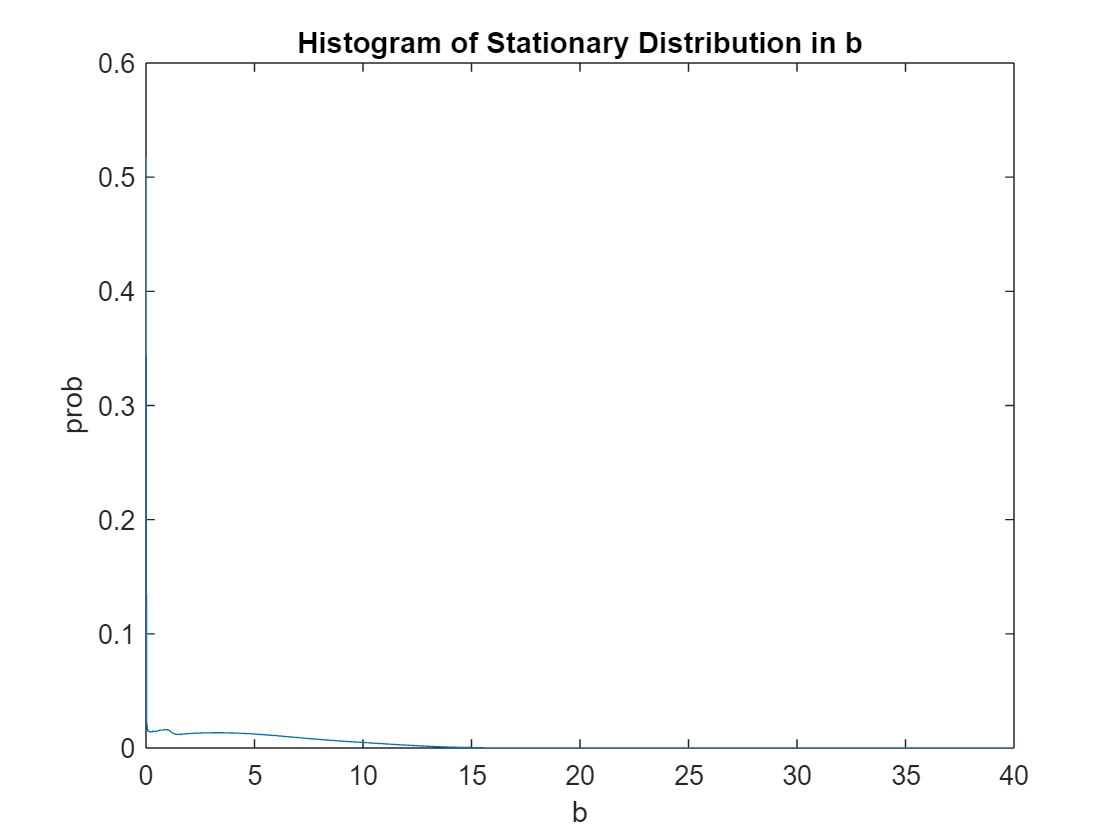

plot(bgrid,dist_b); 
xlabel('b');
ylabel('prob');
title('Histogram of Stationary Distribution in b');

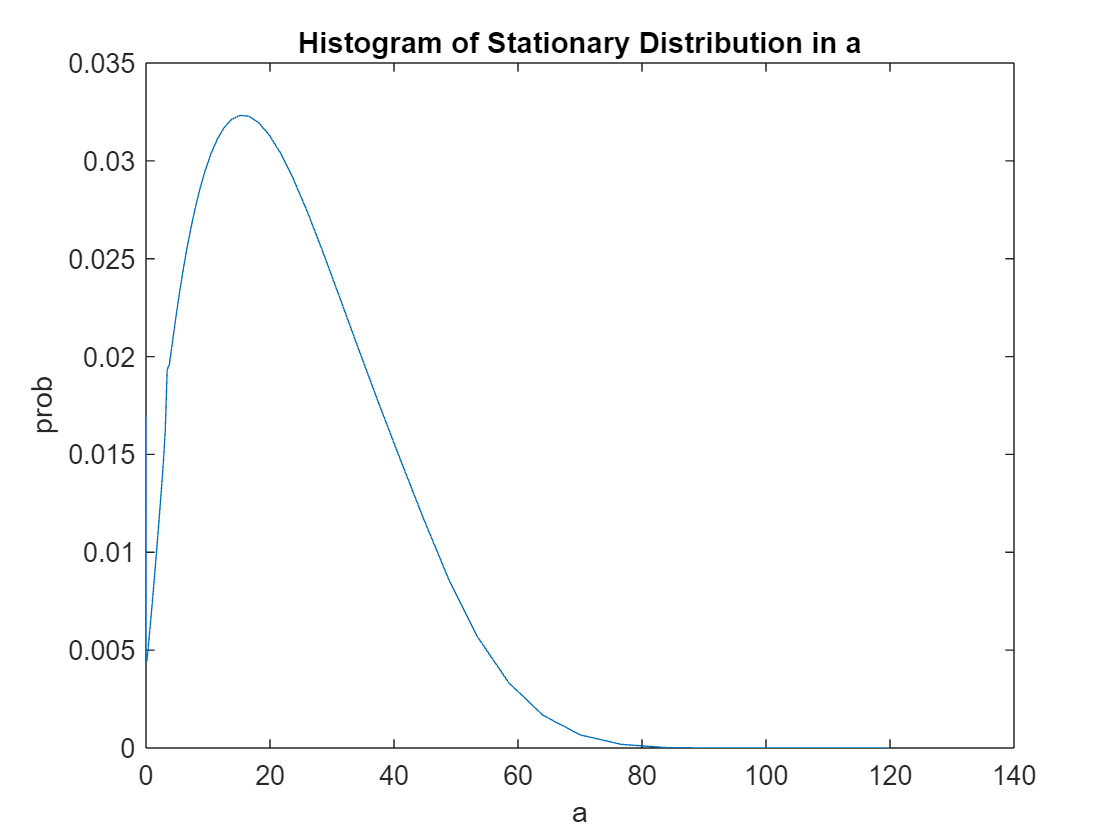

plot(agrid,dist_a); 
xlabel('a');
ylabel('prob');
title('Histogram of Stationary Distribution in a');

# 求解暂时性冲击发生后的转移路径

## 求解线性化的转移路径

我们首先构造针对泰勒规则的货币政策冲击序列：

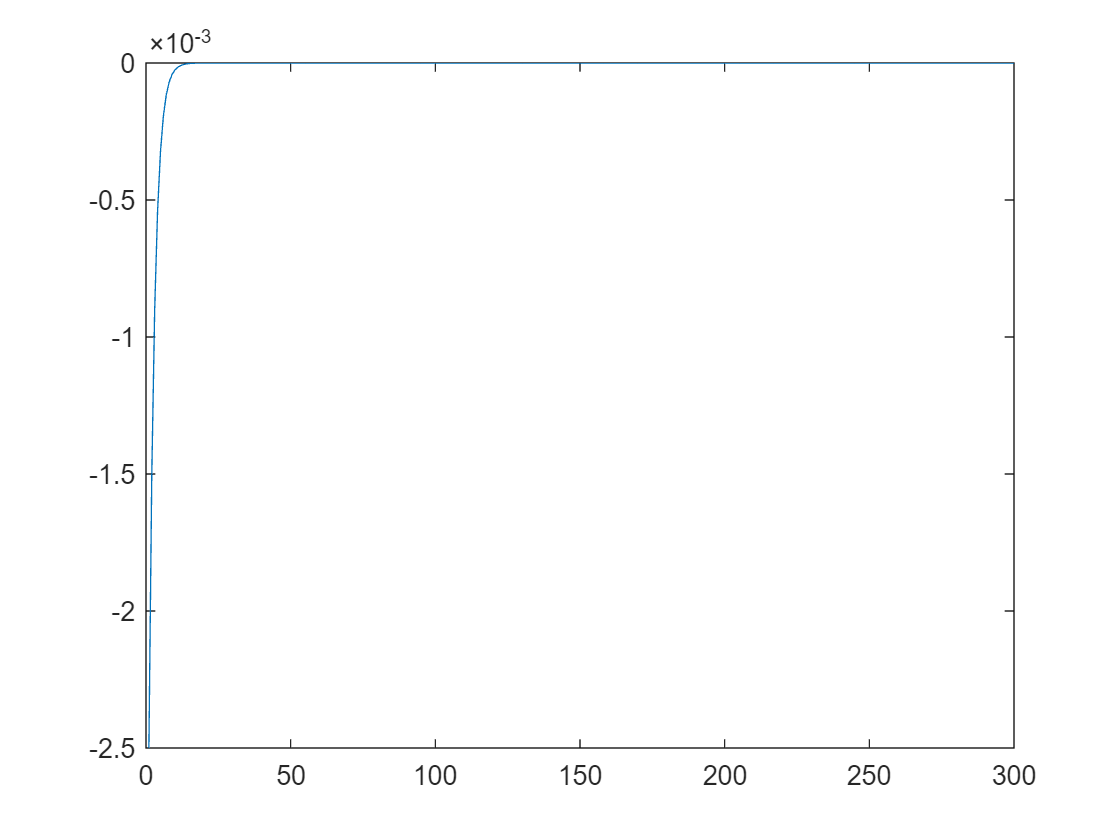

T = 300; % Transition periods
rho_r = 0.6; % persistence of monetary shock
sig_r = -0.01/4; % a negative interest rate shock of 25 basis points
m_shock_t = sig_r * rho_r.^(0:(T-1)); % the path of interest rate shock

figure;
plot(m_shock_t)

我们随后将货币冲击与求解出的 solved ss_rslt 传递到 solve_trans_linear 中，以求解线性化的转移路径。

options = struct;
options.T = T;
options.m_shock_t = m_shock_t;
tic;
trans_linear_rslt = solve_trans_linear(ss_rslt, options);
fprintf('Time used for solving the linearized transition path:\n');toc;

Time used for solving the linearized transition path:
Elapsed time is 64.028450 seconds.


trans_linear_rslt

trans_linear_rslt = struct with fields:
             var_agg_t: [1×1 struct]
       var_agg_shock_t: [1×1 struct]
      jacs_ind_wrt_agg: {5×5 cell}
    jac_eqs_of_var_agg: [2700×2700 double]
               irf_ssj: [2700×300 double]


我们可以画出转移路径 (注意 K 为下一期资本) 。

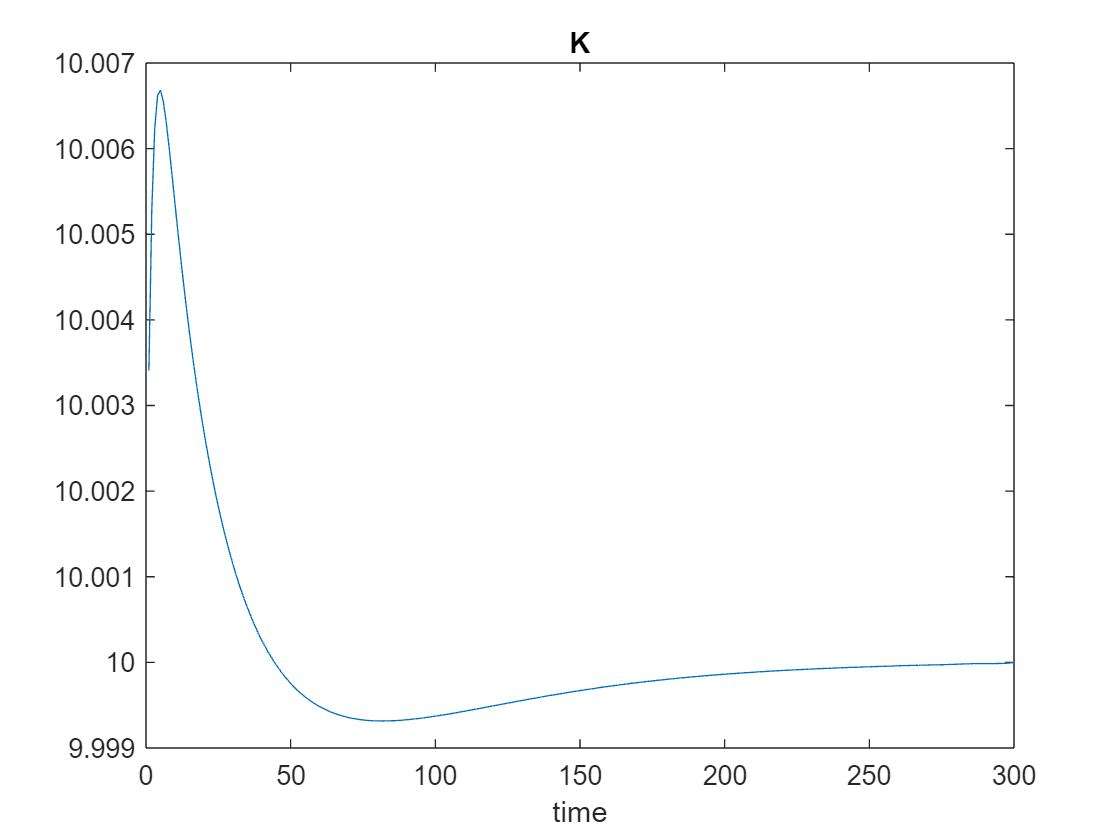

figure;
plot(trans_linear_rslt.var_agg_t.K)
title('K');
xlabel('time');

## 求解非线性转移路径

现在，我们将 solved ss_rslt 传递到 solve_nonlinear_trans (init_ss, final_ss, options) 之中，以求解非线性转移路径。

注意，我们将 ss_rslt 传递到了 init_ss 和 final_ss 之中。

tic;
trans_nonlinear_rslt = solve_trans_nonlinear(ss_rslt, ss_rslt, options);

     Iteration    Line Search     Func-count    ||f(x)||^2     fnorm(x)      Norm of Step      Step Size      Algorithm

             0              0              1   9.999633e-08   3.162220e-04

             1              1              2   2.404074e-10   1.550508e-05   1.405179e-03   1.000000e+00        Broyden


fprintf('Time used for solving the nonlinear transition path:\n');toc;

Time used for solving the nonlinear transition path:
Elapsed time is 113.535368 seconds.


trans_nonlinear_rslt

trans_nonlinear_rslt = struct with fields:
          var_agg_t: [1×1 struct]
    var_agg_shock_t: [1×1 struct]
                  T: 300
           vfi_rslt: [1×1 struct]
        shock_trans: [3×3 double]
           exitflag: 1
             HANS_x: [2700×1 double]
          eqs_resid: [2700×1 double]
          rslt_type: 'nonlinear_trans'
      solver_output: [1×1 struct]


我们可以比较非线性与线性的转移路径结果。

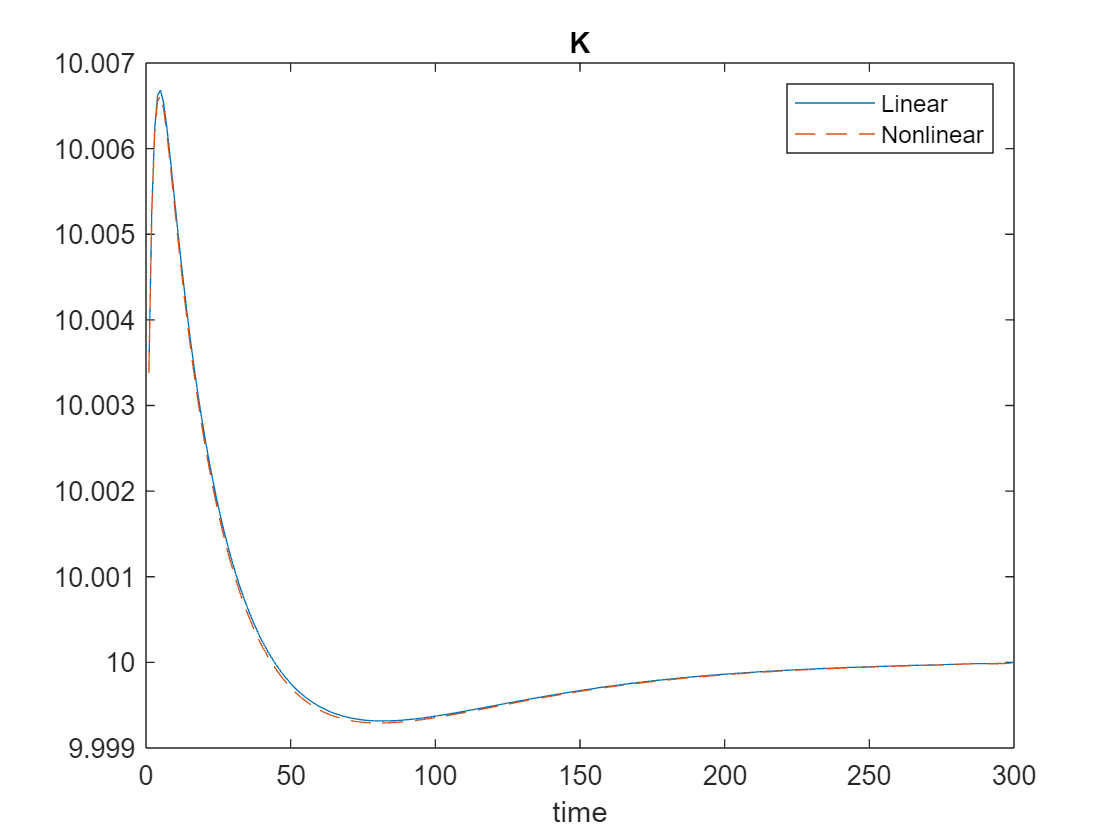

figure;
plot(trans_linear_rslt.var_agg_t.K);
hold on;
plot(trans_nonlinear_rslt.var_agg_t.K, '--');
xlabel('time');
title('K');
legend({'Linear','Nonlinear'});

我们也可以查看转移路径中定义的其他均衡变量。

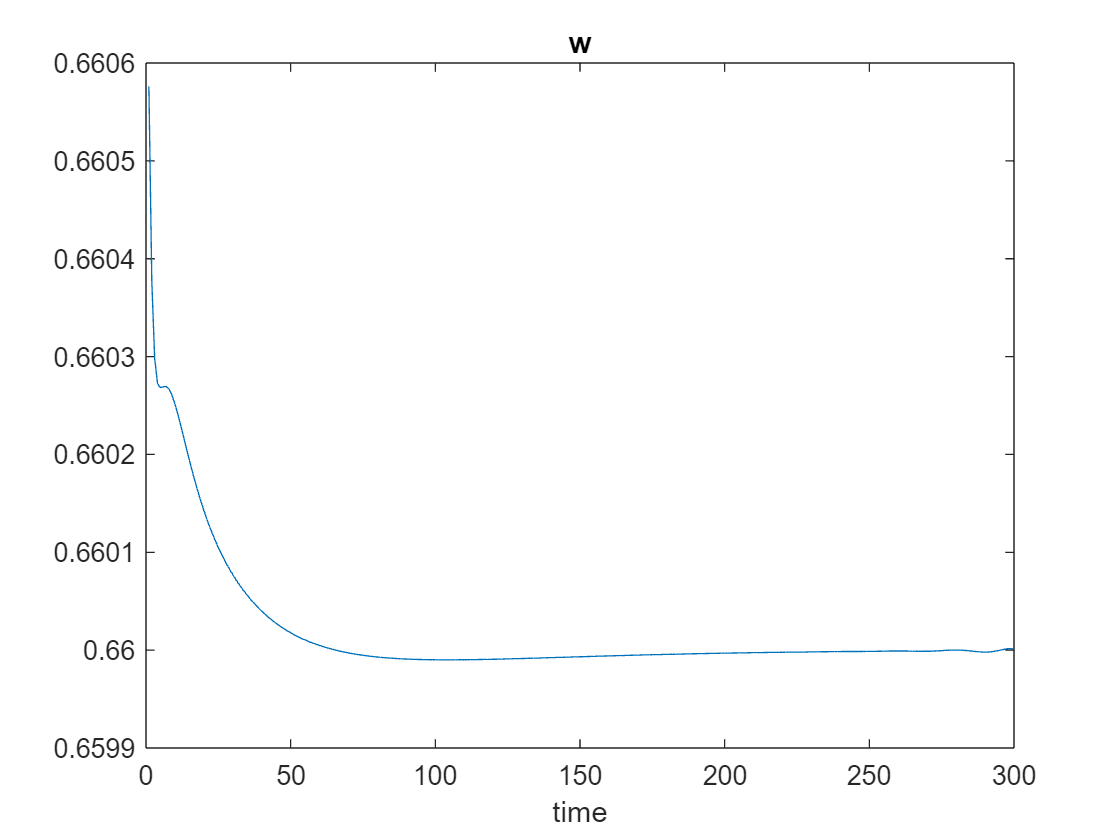

figure;
plot(trans_nonlinear_rslt.var_agg_t.w);
title('w');
xlabel('time');